clear
clc
digits(4)

Definizione masse e gravità

% Massa singola ruota
m_r = sym('3');

% Massa asta
m_a = sym('3.5');

% Massa uomo (da far variare poi)
m_c = sym('70');
w_c = sym('154.3234');

% Massa carello(base) + batterie
m_b = sym('34.4');

% Massa totale del sistema
M = m_a+m_b+m_c+2*m_r;

% Costante gravitazionale
g = sym('9.81');

Definizione inerzie

% Inerzia asta
J_a = sym('0.1669');

% Inerzia della base
J_b = sym('0.6667');

% Inerzia del corpo (TODO: lungo asse z????)
J_c = 0.5 * m_c * (0.25 ^ 2 + 0.35 ^ 2);

% Inerzia della singola ruota
J_r = sym('0.1452');

Definizione delle altezze [m]

% Altezza asta
h_a = sym('1.4');

% Altezza base
h_b = sym('0.2');

% Profondità base
w_b = sym('0.5');

% Posizione baricentro base (valore assoluto)
z_b = sym('0.1');

% Posizione baricentro corpo umano
h_c = sym('1.70'); % Altezza uomo
z_c = 0.55 * h_c;

% Raggio ruota
r_r = sym('0.22')

$$r\_r = 0.22$$

Definizione delle costanti geometriche a e beta (come in immagine)

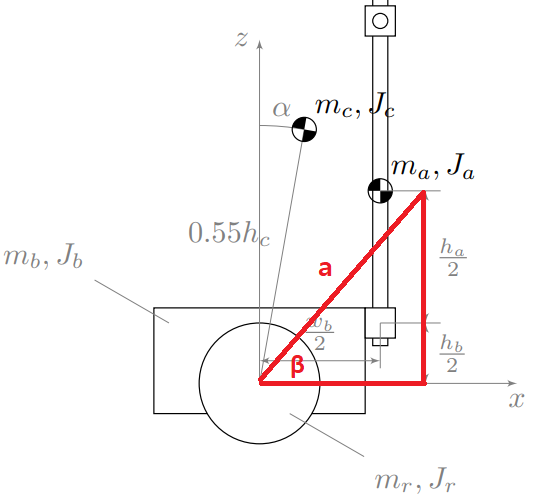

temp_1 = (h_a / 2) + (h_b / 2);
temp_2 = w_b / 2;
%la = vpa(sqrt((temp_1)^2 + (temp_2)^2));
%beta = vpa(atan(temp_1 / temp_2));

Definizione delle variabili

syms t; % tempo
syms T; % energia cinetica del sistema
syms U; % energia potenziale del sistema
syms alpha; % Angolo di offset statico che sposta in avanti il baricentro
syms beta;%altro angolo statico, vedi disegno
% Coordinate libere
syms x(t); % posizione carrello
vel = diff(x, t)

$$vel(t) = \frac{\partial }{\partial t}x\left(t\right)$$

syms theta(t); % angolo inclinazione
syms l_a l_b;
vel_ang = diff(theta, t)

$$vel\_ang(t) = \frac{\partial }{\partial t}\theta \left(t\right)$$

definisco la posizione dei punti

syms q_1 q_1_p q_2 q_2_p;
%definisco il problema per il punto Pa
P_a = [x+l_a*sin(theta+beta);l_a*cos(theta+beta);theta];
V_a = diff(P_a,t);
M_a = [m_a,0,0;0,m_a,0;0,0,J_a];
T_a = 1/2*V_a'*M_a*V_a;
U_a = m_a * g * l_a*cos(theta+beta);
L_a = T_a -U_a;
L_a_q = subs(L_a,{x,vel,theta,vel_ang},{q_1 q_1_p q_2 q_2_p});
diff(T_a_q,q_2_p);
L_a_t = subs(L_a,{q_1 q_1_p q_2 q_2_p},{x,vel,theta,vel_ang});
L_a_dt_t = diff(L_a_t,t)

$$L\_a\_dt\_t(t) = \begin{array}{l} 0.08345\,\sigma_{2}\,\sigma_{3}+0.08345\,\bar{\sigma_{3}}\,\frac{\partial }{\partial t}\theta \left(t\right)+\left(\frac{\partial }{\partial t}x\left(t\right)+l_{a}\,\sigma_{4}\,\frac{\partial }{\partial t}\theta \left(t\right)\right)\,\left(1.75\,\bar{\sigma_{7}}-1.75\,{\sigma_{2}}^{2}\,\bar{l_{a}}\,\sin\left(\sigma_{5}\right)+1.75\,\bar{\sigma_{3}}\,\bar{l_{a}}\,\cos\left(\sigma_{5}\right)\right)+\left(1.75\,\bar{\frac{\partial }{\partial t}x\left(t\right)}+1.75\,\sigma_{2}\,\bar{l_{a}}\,\cos\left(\sigma_{5}\right)\right)\,\left(l_{a}\,\sigma_{4}\,\sigma_{3}-l_{a}\,\sigma_{1}\,\sigma_{6}+\sigma_{7}\right)+34.33\,l_{a}\,\sigma_{1}\,\frac{\partial }{\partial t}\theta \left(t\right)+1.75\,l_{a}\,\sigma_{4}\,\sigma_{2}\,\bar{l_{a}}\,\sin\left(\sigma_{5}\right)\,\sigma_{6}+1.75\,l_{a}\,\sigma_{1}\,{\sigma_{2}}^{2}\,\bar{l_{a}}\,\cos\left(\sigma_{5}\right)\,\frac{\partial }{\partial t}\theta \left(t\right)+1.75\,l_{a}\,\sigma_{1}\,\sigma_{2}\,\bar{l_{a}}\,\sin\left(\sigma_{5}\right)\,\sigma_{3}+1.75\,l_{a}\,\sigma_{1}\,\bar{\sigma_{3}}\,\bar{l_{a}}\,\sin\left(\sigma_{5}\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\beta +\theta \left(t\right)\right)\\ \sigma_{2}=\bar{\frac{\partial }{\partial t}\theta \left(t\right)}\\ \sigma_{3}=\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)\\ \sigma_{4}=\cos\left(\beta +\theta \left(t\right)\right)\\ \sigma_{5}=\bar{\theta \left(t\right)}+\bar{\beta }\\ \sigma_{6}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\\ \sigma_{7}=\frac{\partial^{2}}{\partial t^{2}}x\left(t\right) \end{array}$$

clear

$$L\_q(t) = \frac{m\,l^{2}\,{q_{2,p}}^{2}}{2}+m\,\cos\left(q_{2}\right)\,l\,q_{1,p}\,q_{2,p}+g\,m\,\cos\left(q_{2}\right)\,l+\left(\frac{M}{2}+\frac{m}{2}\right)\,{q_{1,p}}^{2}$$

$$risultato(t) = m\,l^{2}\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+m\,\cos\left(\theta \left(t\right)\right)\,l\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+g\,m\,\sin\left(\theta \left(t\right)\right)\,l$$

clc
%%%%%provo con il caso di ermidoro per vedere se è giusto
syms q_1 q_1_p q_2 q_2_p t m M l g;
syms x(t); % posizione carrello
vel = diff(x, t);
syms theta(t); % angolo inclinazione
vel_ang = diff(theta, t);
T = 0.5*(m+M)*vel^2+0.5*m*l^2*vel_ang^2+m*l*vel_ang*vel*cos(theta);
U = -m*g*l*cos(theta);
L = T - U;
L_q = subs(L,{x,vel,theta,vel_ang},{q_1 q_1_p q_2 q_2_p})
dL_dq_2_p = diff(L_q,q_2_p);
dL_dvel_ang = subs(dL_dq_2_p,{q_1 q_1_p q_2 q_2_p},{x,vel,theta,vel_ang});
dL_dt = diff(dL_dvel_ang,t);
dL_dq_2 = diff(L_q,q_2);
dL_dtheta = subs(dL_dq_2,{q_1 q_1_p q_2 q_2_p},{x,vel,theta,vel_ang});
risultato = dL_dt-dL_dtheta

Definizione dell'energia cinetica del sistema (indipendente dal tempo)

% 
% % Energia cinetica singola ruota
% T_r = 0.5 * m_r * q_1_p^2 + vpa(0.5 * J_r) * (q_1_p / r_r)^2
% 
% % Energia cinetica base (contributo energia cinetica "lineare" e
% % rotazionale)
% T_b = vpa(0.5 * m_b) * q_1_p^2 + vpa(0.5 * J_b) * q_2_p ^ 2
% 
% % Energia cinetica asta (contributo energia cinetica "lineare" e
% % rotazionale)
% T_a = vpa(0.5 * m_a) * q_1_p^2 + vpa(0.5 * J_a) * q_2_p ^ 2
% 
% % Energia cinetica corpo (contributo energia cinetica "lineare" e
% % rotazionale)
% T_c = vpa(0.5 * m_c) * q_1_p^2 + vpa(0.5 * J_c) * q_2_p ^ 2
% 
% T = 2 * T_r + T_b + T_a + T_c

Definizione dell'energia potenziale

% % Energia potenziale base
% U_b = - vpa(m_b * g * z_c * cos(q_2)) 
% 
% % Energia potenziale asta (manubrio)
% U_a = vpa(m_a * g * a * cos(beta + q_2))
% 
% % Energia potenziale corpo
% U_c = vpa(m_c * g * z_c * cos(alpha + q_2))
% 
% U = U_b +  U_a + U_c

Definizione della Lagrangiana

% L = T - U

Calcolo delle equazioni di moto

% % theta -> ang_car -> q_2   theta'-> vel_ang_car -> q_2_p
% 
% % dL/dq_2
% dL_dq2= diff(L, q_2)
% dL_dq2_t = subs(dL_dq2, {q_1, q_1_p, q_2, q_2_p}, {x, vel, theta, vel_ang})
% 
% % dL/dq_2_p
% dL_dq2p= diff(L,q_2_p)
% dL_dq2p_t = subs(dL_dq2p, {q_1, q_1_p, q_2, q_2_p}, {x, vel, theta, vel_ang})
% 
% % d(dL_dq1p)/dt
% dL_dq2p_dt = diff(dL_dq2p_t, t)
% 
% dL_dq2p_dt - dL_dq2p_t == 0

**guarda qui piffo prima di passare dopo**

% clc
% clear
% syms t
% syms x x_f(t)
% k = cos(x^2 * x_f)
% temp3 = diff(k, x)
% %temp = diff(k,t)
% vel = diff(x_f, t)
% temp2 = subs(temp3,{x},{vel})
% 
% diff(temp2,t)

If you want to differentiate L with respect to q, q must be a variable. You can use `subs` to replace it with a function and calculate  the derivative later:

% syms t x teta vel omega h L1 M1        % variables
% %valori di T e U a caso, per fare una prova
% T = 1/2*5*vel^2
% U = 5*10*h
% L = T-U
% %dL/dq'
% dLdvel= diff(L,vel)
% %dL/dq
% dLdx = diff(L,x)
% %creo alrtre variabili dipendenti dal tempo questa volta
% syms x_f(t) teta_f(t) h_f(t)  % functions
% %calcolo le derivate delle variabili di cui sopra
% vel_f(t)= diff(x_f,t)
% omega_f(t)= diff(teta_f,t)
% dh_f(t) = diff(h_f,t)
% %sostituisco le variabili dipendenti dal tempo a qelle indipendenti
% dLdqt_f= subs(dLdvel,{x,teta,h,vel,omega},{x_f,teta_f,h_f,vel_f,omega_f})
% dLdq_f = subs(dLdx,{x,teta,h,vel,omega},{x_f,teta_f,h_f,vel_f,omega_f})
% dLdveldt = diff(dLdqt_f,t)
% %risolvo l'equazione
% ris = dsolve(dLdveldt-dLdq_f==0)
% %non so ancora interpretare il risultato, immagino sia
% %la risoluzione di una equazione differenziale
% 